syms mu_1 mu_2 sigma_1 sigma_2 rho x m n real

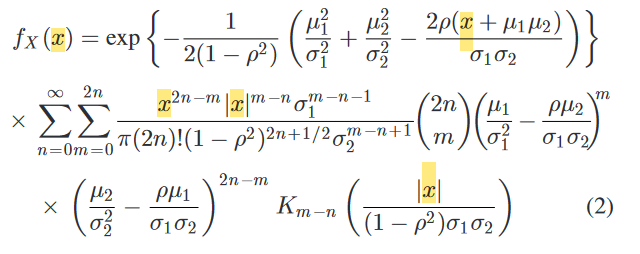

## Terms before the sum

GaussianProductPdfBeforeTheSum(x, mu_1, mu_2, sigma_1, sigma_2, rho)

$$ans = {\mathrm{e}}^{\frac{\frac{{\mu_{1}}^{2}}{{\sigma_{1}}^{2}}+\frac{{\mu_{2}}^{2}}{{\sigma_{2}}^{2}}-\frac{2\,\rho \,\left(\mu_{1}\,\mu_{2}+x\right)}{\sigma_{1}\,\sigma_{2}}}{-2+2\,\rho^{2}}}$$

## Terms inside the sum

GaussianProductPdfInsideTheSum(x, mu_1, mu_2, sigma_1, sigma_2, rho, m, n)

$$ans = \frac{x^{2\,n-m}\,Y_{-n+m}\left(-\frac{\left|x\right|}{\sigma_{1}\,\sigma_{2}\,\left(-1+\rho^{2}\right)}\right)\,\left({2\,n \atop m}\right)\,{\left(\frac{\mu_{1}}{{\sigma_{1}}^{2}}-\frac{\mu_{2}\,\rho }{\sigma_{1}\,\sigma_{2}}\right)}^{m}\,{\left(\frac{\mu_{2}}{{\sigma_{2}}^{2}}-\frac{\mu_{1}\,\rho }{\sigma_{1}\,\sigma_{2}}\right)}^{2\,n-m}}{{\sigma_{1}}^{1+n-m}\,{\sigma_{2}}^{1-n+m}\,\pi \,\left(2\,n\right)!\,{\left|x\right|}^{n-m}\,{\left(1-\rho^{2}\right)}^{\frac{1}{2}+2\,n}}$$

syms mu_1 mu_2 sigma_1 sigma_2 rho x m n

## Define parameters

m1 = 2;
m2 = 1.5;
s1 = 0.5;
s2 = 0.7;
r = 0.1;
X = linspace(-4, 14, 100);

## Sample distribution based on paramers

s12 = r*s1*s2;
samples = mvnrnd([m1; m2],[s1^2 s12; s12 s2^2],100000);
X1 = samples(:,1);
X2 = samples(:,2);
Z = X1.*X2;

## Print results

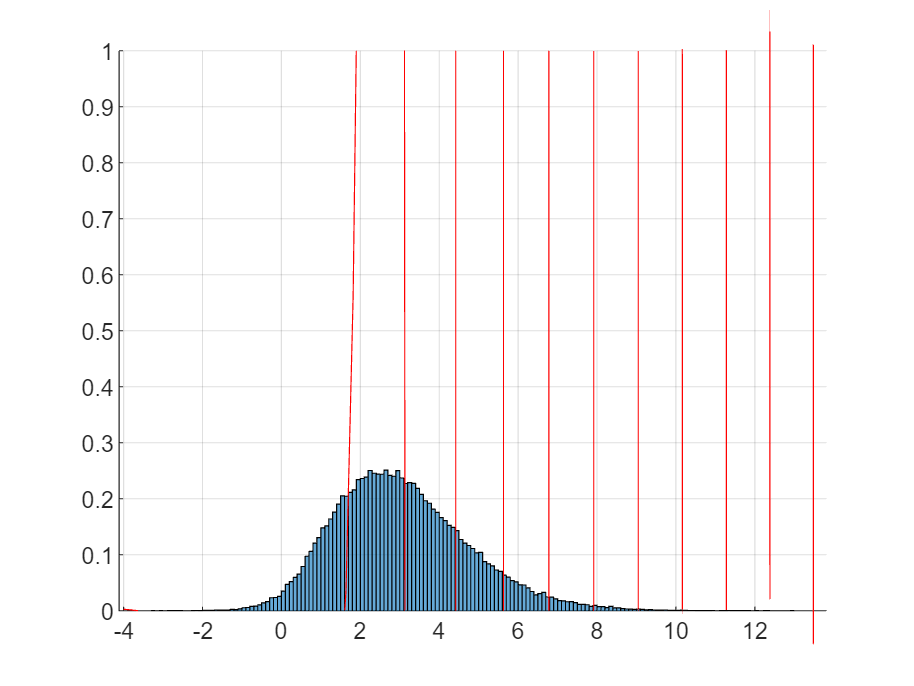

figure; hold on; grid on
histogram(Z, Normalization="pdf");
plot(X, GaussianProductPdf(X, m1, m2, s1, s2, r, 10), 'r');
ylim([0 1])

function y = GaussianProductPdf(x, m1, m2, s1, s2, r, N)
    y = GaussianProductPdfBeforeTheSum(x, m1, m2, s1, s2, r);
    sums = zeros(size(x));
    for n = 0:N
        for m = 0:2*n
            sums = sums ...
                + GaussianProductPdfInsideTheSum(x, m1, m2, s1, s2, r, m, n);
        end
    end
    y = y.*(sums);
end

function y = GaussianProductPdfBeforeTheSum(x, m1, m2, s1, s2, r)
    y=exp(-1/(2*(1-r^2)) ...
            *(...
                  m1^2/s1^2 ...
                + m2^2/s2^2 ...
                - (2*r).*(x+m1*m2)./(s1*s2)...
             )...
         );
end

function y = GaussianProductPdfInsideTheSum(x, m1, m2, s1, s2, r, m, n)
    y = x.^(2*n-m).*abs(x).^(m-n) ...
        .* inv(pi*factorial(2*n)*(1-r^2)^(2*n+1/2)) ...
        .* (s1^(m-n-1))/(s2^(m-n+1)) ...
        .* nchoosek(2*n,m) ...
        .* ( (m1/s1^2)-((r*m2)/(s1*s2)) )^m ...
        .* ( (m2/s2^2)-((r*m1)/(s1*s2)) )^(2*n-m) ...
        .* bessely(m-n,abs(x)./((1-r^2)*s1*s2));
end